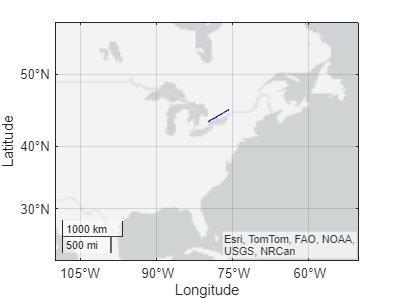

function flight_path = flight_pathing(flightduration, startlat, startlong, endlat, endlong)

    mission.StartDate = datetime;

    mission.Duration = hours(flightduration);
    
    start.Lat = startlat; % Starting Latitude
    start.Long = startlong; % Starting Longitude
    
    ending.Lat = endlat; % Ending Latitude
    ending.Long = endlong; % Ending Longitude
    
    traj.Lat = ending.Lat - start.Lat; % Determine change in Latitude
    traj.Long = ending.Long - start.Long; % Determine change in Longitude
    
    durationseconds = flightduration * 3600; % Convert duration into seconds
    samples = durationseconds / 10; % Convert to sample count
    
    flight.Latdelta = traj.Lat/samples;
    flight.Longdelta = traj.Long/samples;
    
    moment.Missiontime = 0;
    moment.Lat = start.Lat;
    moment.Long = start.Long;
    
    matObj = matfile("trajectory.mat");
    m = matfile('trajectory.mat','Writable',true);
    flighttime = timetable(TimeStep=seconds(10));
    trajtime = createArray(samples+1,3);
    
    for i = 1:samples+1
        trajtime(i,1) = moment.Lat;
        trajtime(i,2) = moment.Long;
        trajtime(i,3) = 10000;
        moment.Lat = moment.Lat + flight.Latdelta;
        moment.Long = moment.Long + flight.Longdelta;
    end
    
    flighttime.LLA = trajtime;
    % m.trajectory = flighttime;
    flight_path = flighttime;
end


function [missionout, aircraftout] = create_mission(startdate, flightduration, startlat, startlong, endlat, endlong)
    % Create flight
    missionout.StartDate = startdate;
    missionout.Duration = hours(flightduration);
    pathing = flight_pathing(flightduration, startlat, startlong, endlat, endlong);
    m = matfile('trajectory.mat','Writable',true);
    m.trajectory = pathing;
    aircraftout = load("trajectory.mat", "trajectory"); % Created using flight_pathing.mlx
    geoplot(aircraftout.trajectory.LLA(:,1), aircraftout.trajectory.LLA(:,2), "b-");
    geolimits([30 50],[-110 -50]);
    
    % Create Mission
    missionout.scenario = satelliteScenario(missionout.StartDate, ...
        missionout.StartDate + missionout.Duration, 60);
    missionout.viewer = satelliteScenarioViewer(missionout.scenario);
    aircraftout.obj = satellite(missionout.scenario,aircraftout.trajectory, CoordinateFrame="geographic", Name="Aircraft");
    aircraftout.obj.MarkerColor = "green";
    hide(aircraftout.obj.Orbit);
    show(aircraftout.obj.GroundTrack);
end



function constellationout = create_satellite(missionin, radius, inclination, totalcount, planes, phasing, lat)
    % Establish values
    constellationout.Radius = radius;
    constellationout.Inclination = inclination;
    constellationout.TotalSatellites = totalcount;
    constellationout.GeometryPlanes = planes;
    constellationout.Phasing = phasing;
    constellationout.ArgLat = lat;

    % Create constellation
    constellationout.obj = walkerDelta(missionin.scenario, ...
    constellationout.Radius, ...
    constellationout.Inclination, ...
    constellationout.TotalSatellites, ...
    constellationout.GeometryPlanes, ...
    constellationout.Phasing, ...
    ArgumentOfLatitude=constellationout.ArgLat, ...
    Name="Satellite");
end


function accessAnalysisTable = Access_Analysis(constellationobject, aircraftobject)
    accessAnalysisTable.obj = access(constellationobject.obj, aircraftobject.obj);
    accessAnalysisTable.Intervals = accessIntervals(accessAnalysisTable.obj);
    accessAnalysisTable.Intervals = sortrows(accessAnalysisTable.Intervals,"StartTime");
    disp(accessAnalysisTable.Intervals);
end


function fix_table(accesstable)
    % Get access stuff we want
    [sourcechars, targetchars, startchars, endchars, durationchars] = convertStringsToChars(accesstable.Intervals.Source,accesstable.Intervals.Target, ...
        string(accesstable.Intervals.StartTime),string(accesstable.Intervals.EndTime), accesstable.Intervals.Duration);
    chartable = table(sourcechars, targetchars, startchars, endchars, durationchars);
    celltable = table2cell(chartable);
    figure2 = figure("Name", "Access Analysis", "NumberTitle","off");
    figure(figure2);
    
    
    % Make a better table
    tablepic = uitable(figure2, 'ColumnWidth', 'auto', "Data", celltable);
    tablepic.ColumnName = {"Source","Target","Start Time","End Time","Duration"};
    table_extent = get(tablepic,'Extent');
    set(tablepic,'Position',[1 1 table_extent(3) table_extent(4)]);
    figure_size = get(figure2,'outerposition');
    desired_fig_size = [figure_size(1) figure_size(2) table_extent(3)+50 table_extent(4)+50];
    set(figure2,'outerposition', desired_fig_size);
end


starting = datetime(2024,9,6,9,0,0);
[mission, aircraft] = create_mission(starting, 2.5, 43.667, -79.6634, 45.3178, -75.6659);

constellation = create_satellite(mission, 7200000, 70, 12, 4, 1, 15);
accessanalysistest = Access_Analysis(constellation, aircraft);

        Source          Target      IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ______________    __________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite_10"    "Aircraft"          1           06-Sep-2024 09:00:00    06-Sep-2024 09:12:00       720          1            1    
    "Satellite_1"     "Aircraft"          1           06-Sep-2024 09:04:00    06-Sep-2024 09:20:00       960          1            1    
    "Satellite_12"    "Aircraft"          1           06-Sep-2024 09:31:00    06-Sep-2024 09:48:00      1020          1            1    
    "Satellite_3"     "Aircraft"          

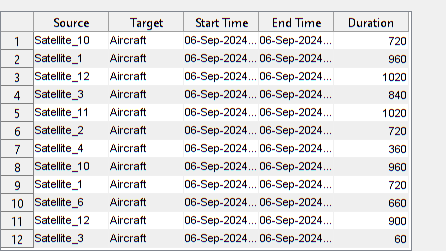

fix_table(accessanalysistest)